%% ADMM-Factorization on AT&T Face Dataset
clearvars;
clc;
rng(0); 

%% === Dataset Info ===
% The AT&T Database of Faces has 40 subjects, each with 10 images
% Images are 112x92 grayscale PGM files.
% Folder structure: att_faces/s1/1.pgm, s1/2.pgm, ..., s40/10.pgm

dataDir = "C:\Users\kisor\Academics\SEM-3\MFC - 3\Project\Matrix Completion\Codes\Dataset\AT&T Database of Faces"; % change to your AT&T folder path

subjects = 40;
imgs_per_subject = 10;
img_h = 112;
img_w = 92;

%% === Choose one image for demo (can loop over all) ===
subj_id = 3; img_id = 3;
imgPath = fullfile(dataDir, sprintf('s%d', subj_id), sprintf('%d.pgm', img_id));
img = imread(imgPath);
img = double(img) % convert to double for math

img =    101   106   102   104   104   102   108   108   104   108   101   107   110   106   107   108   108   110   108   101    79    75    89    99   113   115   110   108   102    98    99    95    93    84   109   117   133   121   124   154   135   120   116   113   110   104   102   102   114   111
   101   104   102   106   102   104   104   108   103   106   103   108   106   109   106   111   105   107    92    78    61    73    90    97   108   118   110   111    99    94    92    87    87    75    99   132   163   155   150   179   191   189   166   149   119   113   102   107    95   108
    99   104   102   106   102   102   107   101   107   106   105   110   104   107   106   109   108   104    83    67    51    72    87   100   100   109   112   109   113   107   107    95   110   118   103   115   142   158   150   151   161   176   179   174   159   113   103   100    92    88
   100   107    98   106   105   102   108   104   104   110   104   110   107   112   105 


dataDir1 = "C:\Users\kisor\Academics\SEM-3\MFC - 3\Project\Matrix Completion\Codes\Dataset\AT&T Database of Faces\s3\TESTimg.jpg"

dataDir1 = "C:\Users\kisor\Academics\SEM-3\MFC - 3\Project\Matrix Completion\Codes\Dataset\AT&T Database of Faces\s3\TESTimg.jpg"

img = double(imresize(rgb2gray(imread(dataDir1)),[112 92]));


[m, n] = size(img)

m = 112

n = 92


%% === Create mask with >50% observed pixels ===
SR = 0.5; % sampling ratio
Omega = rand(m, n) < SR; % logical mask
M = img .* Omega       % observed entries only

M =      0   248     0   255     0     0   238     0     0   188   184   181     0   168   165     0     0   178   181     0   185     0   188   188     0   190   190   190     0   191     0     0   192   195   192     0     0   180   180     0   179   175   175     0     0   183     0   181     0   178
     0     0     0   255   255   255   230   194   191   188   184   181     0     0     0     0   170     0   180   182     0   185   186     0     0   188   188   188   188     0   190   190   191   184     0   179   185   189   182     0     0     0     0     0   182   182   181   179   179   177
   252   252   254   255     0     0   222     0   190   187   184     0   177   170   165     0   169     0   176     0     0   183   184   185     0     0     0     0     0     0     0     0     0     0     0     0   204     0   174     0   176     0   170     0   181   181   179     0   178     0
     0     0   255   255   255   254     0     0     0     0   184     0     0     0   166   


%% === ADMM Parameters ===
r =10;           % estimated rank for faces (paper uses 10)
tol = 1e-10;      % strict tolerance for images
maxiter = 2000;    % maximum iterations
rho = 1e8;        % penalty parameter (large for stability)
gamma = 1.0;      % dual step size
c_status = "Not Converged"

%% === Initialization ===
Y = rand(r, n);
Z = M;
Lambda = zeros(m, n);

% Initial X
Yt = Y';
A = Y * Yt;
A_inv = pinv(A);
X = (Z * Yt) * A_inv;

err_hist = zeros(maxiter,1);

%% === ADMM Loop ===
tic;
for iter = 1:maxiter
    % Step 1: Update X
    Yt = Y';
    A = Y * Yt;
    A_inv = pinv(A);
    X = (Z * Yt) * A_inv;
    
    % Step 2: Update Y
    Xt = X';
    B = Xt * X;
    B_inv = pinv(B);
    Y = B_inv * (Xt * Z);
    
    % Step 3: Update Z
    XY = X * Y;
    Z_Omega = (1 / (1 + rho)) * ((XY - Lambda) .* Omega + rho * M .* Omega);
    Z_Omega_c = XY .* (~Omega);
    Z = Z_Omega + Z_Omega_c;
    
    
    % Step 4: Update Lambda (only observed entries)
    Delta = (Z - M) .* Omega;
    Lambda(Omega) = Lambda(Omega) + gamma * rho * Delta(Omega);
    
    % Convergence check
    numer = norm((Z - XY) .* Omega, 'fro');
    denom = max(1, norm(M .* Omega, 'fro'));
    rel_error = numer / denom;
    err_hist(iter) = rel_error;
    
    if rel_error < tol
        c_status = "Converged"
        break;
    end
end
time_taken = toc;

%% === Final Reconstruction ===
Z_completed = X * Y;
Z_completed(Omega) = M(Omega);

%% === Report ===
fprintf('AT&T Faces — ADMM-Factorization\n');

AT&T Faces — ADMM-Factorization


fprintf('Image size: %dx%d, Rank: %d\n', m, n, r);

Image size: 112x92, Rank: 10


fprintf('Sampling ratio: %.2f%%\n', SR*100);

Sampling ratio: 50.00%


fprintf('Iterations: %d, Time: %.2f seconds\n', iter, time_taken);

Iterations: 2000, Time: 0.67 seconds


fprintf('Final Relative Error (observed): %.2e\n', rel_error);

Final Relative Error (observed): 3.33e-02


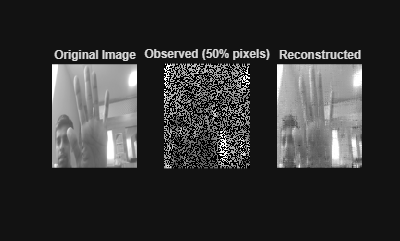


%% === Show Results ===
figure;
subplot(1,3,1);
imshow(uint8(img));
title('Original Image');

subplot(1,3,2);
imshow(uint8(M));
title(sprintf('Observed (%.0f%% pixels)', SR*100));

subplot(1,3,3);
imshow(uint8(Z_completed));
title('Reconstructed');